tic
% % ts = read_log_v13("../LOGS/log1260.csv");
ts2 = read_log_v13("../LOGS/log1382.csv");

Loaded 373000 samples, t = [0.000, 372.999] s (373.0 s), 4 actuators


ts = read_log_v13("../LOGS/log1441.csv")

Loaded 84230 samples, t = [0.000, 84.229] s (84.2 s), 4 actuators


ts = struct with fields:
                    t: [84230×1 double]
                  act: [1×4 struct]
    manifold_pressure: [84230×1 double]
         manifold_raw: [84230×1 double]
      thrust_measured: [84230×1 double]
           thrust_raw: [84230×1 double]
                    T: [84230×66 table]




toc

Elapsed time is 5.585139 seconds.


speedFilter = (abs(ts.act(1).valveVelocity) < 200) & (ts.t<29)&(ts.t>19);
figure
h1 = subplot(2,1,1)

h1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


plot(ts.t(speedFilter), ts.act(1).current_measured(speedFilter))
hold on
plot(ts.t(speedFilter), ts.act(1).current_demand(speedFilter))
grid on
h2 = subplot(2,1,2)

h2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


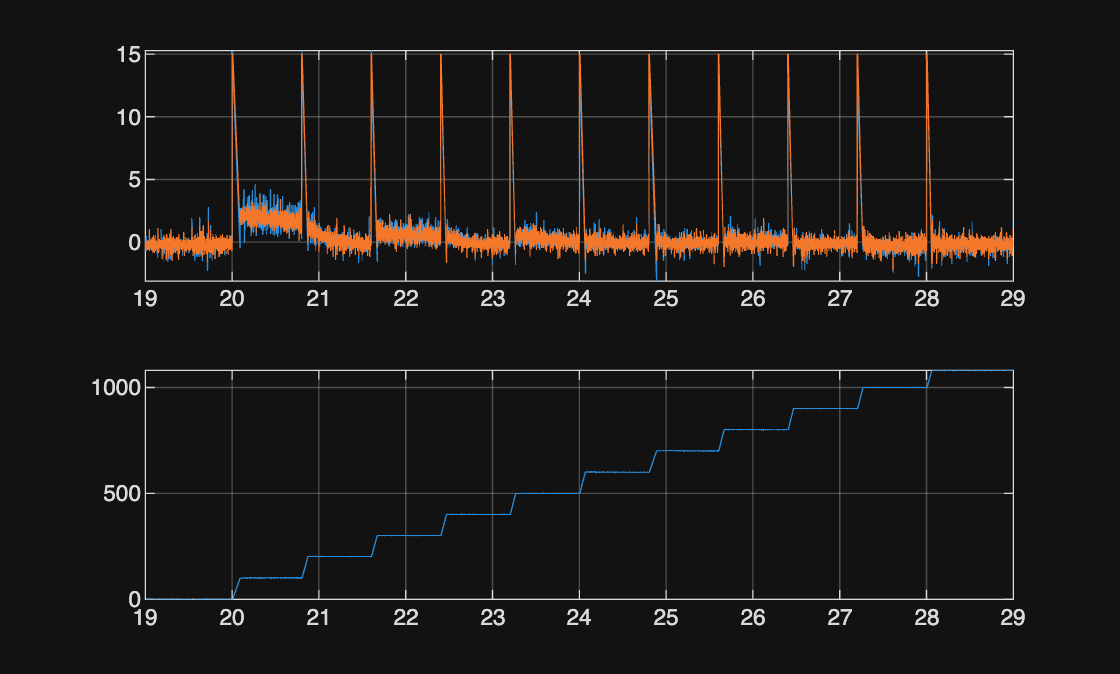

plot(ts.t(speedFilter), ts.act(1).valveAngle(speedFilter))
linkaxes([h1 h2],'x');
grid on

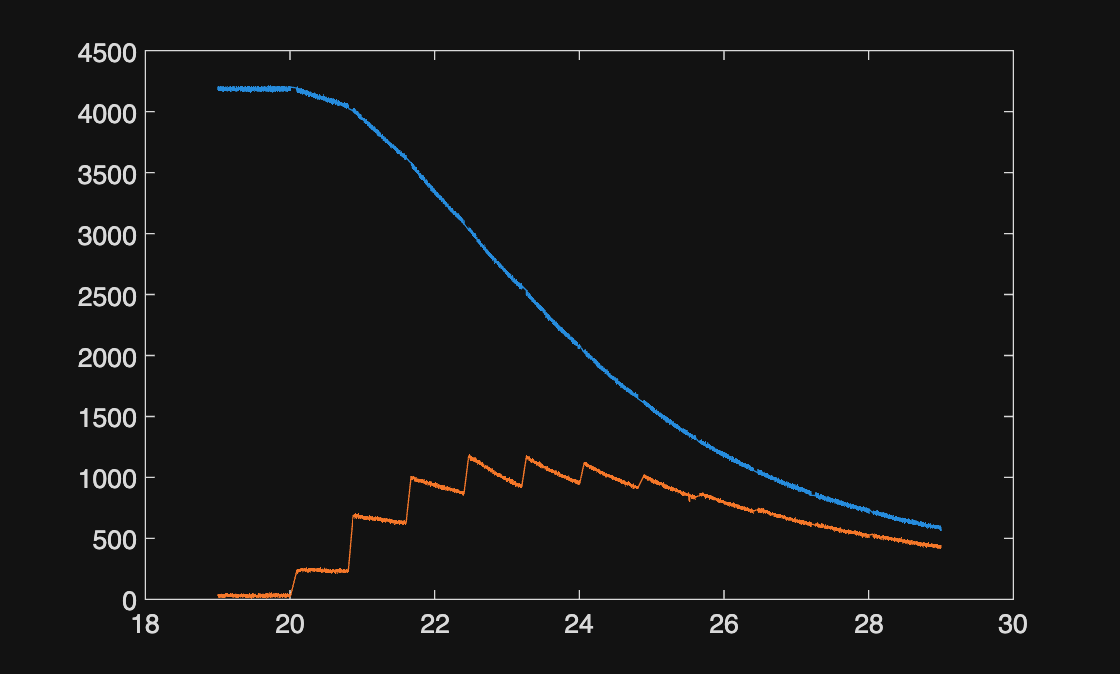

figure 
plot(ts.t(speedFilter), ts.manifold_pressure(speedFilter))
hold on
plot(ts.t(speedFilter), ts.act(1).nozzle_pressure(speedFilter))

figure
speed = abs(ts.act(1).valveVelocity);
% speedFilter = (abs(ts.act(1).valveVelocity) < 200) & (ts.t<29)&(ts.t>19);

angle = ts.act(1).valveAngle(speedFilter);
nozzlePressure = ts.act(1).nozzle_pressure(speedFilter);
manifoldPressure = ts.manifold_pressure(speedFilter);

% angle = angle(speedFilter);
% nozzlePressure = nozzlePressure(speedFilter);
% manifoldPressure = manifoldPressure(speedFilter);
% create a colormap that transitions from one color at t=0 to another at t=30
c1 = [0 1 0]; % color at t=0 (blue)
c2 = [0.8500 0.3250 0.0980]; % color at t=30 (orange)
t_vals = ts.t(speedFilter);            % time vector corresponding to plotted points
t_norm = (t_vals - t_vals(1)) / (t_vals(end) - t_vals(1));      % normalize to [0,1] over 0..30
t_norm = max(0, min(1, t_norm));      % clamp to [0,1]
cols = (1 - t_norm) .* c1 + (t_norm) .* c2; % Nx3 colors

% plot points with color gradient (scatter used to apply per-point colors)
scatter(angle, nozzlePressure ./ manifoldPressure, 15, cols)
hold on
% plot(angle, nozzlePressure ./ manifoldPressure,'.')
hold on
simCoef = [9.963541300115264e-19	-5.638521979549971e-15	1.190871790366917e-11	-1.175632806688227e-08	4.809807875021960e-06	3.275236631208533e-04	0];

linAngle = linspace(0,1080,1000);
responseCurve = polyval(simCoef, linAngle);
% figure;
% plot(linAngle, responseCurve);
xlabel('Valve Angle');
ylabel('Pressure Ratio');
title('Response Curve');
grid on;

% Richards / generalized logistic, lower asymptote fixed at 0
ft = fittype('L*(1 - exp(-(x/tau)^n))', 'independent', 'x','coefficients', {'L','tau','n'});
opts = fitoptions(ft);
opts.StartPoint = [0.75, 480, 1.7];   % [L, tau, n]
opts.Lower      = [0.5,  100, 0.8];
opts.Upper      = [1.0,  1000, 4];
pr = nozzlePressure./manifoldPressure;
mask = angle >= 0;
[f, gof] = fit(angle(mask), pr(mask), ft, opts);


disp(f); disp(gof.rsquare);

     General model:
     f(x) = L*(1 - exp(-(x/tau)^n))
     Coefficients (with 95% confidence bounds):
       L =      0.7772  (0.776, 0.7784)
       tau =       519.7  (518.4, 520.9)
       n =        1.52  (1.515, 1.524)
    0.9978



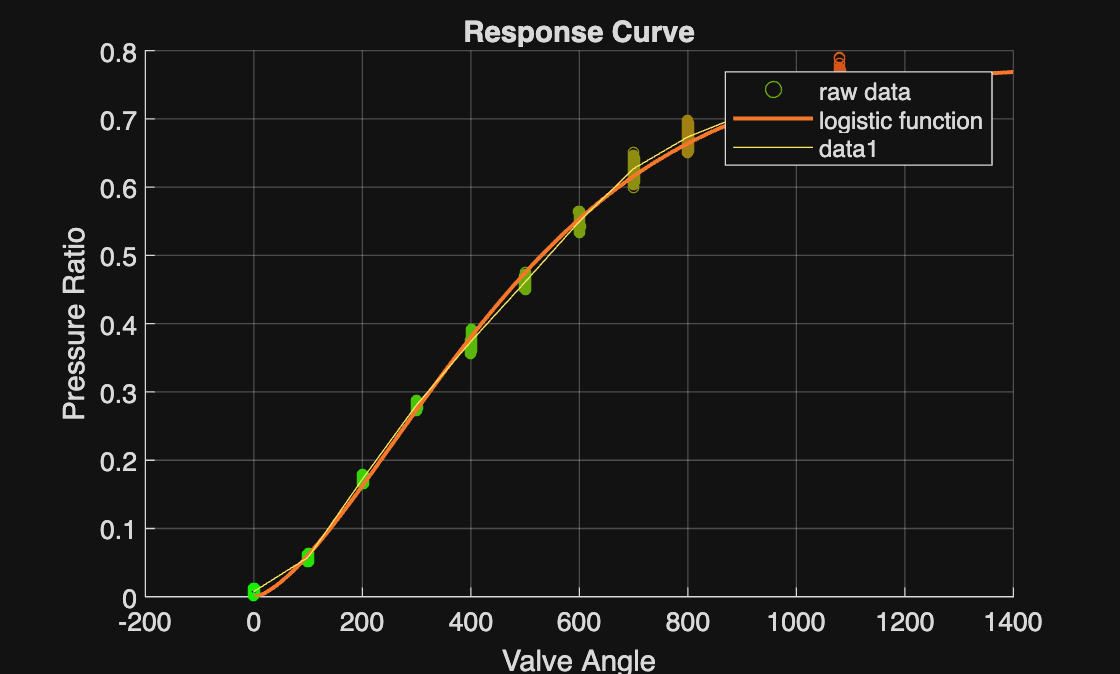


% plot
xq = linspace(0, 1400, 500);
plot( xq, f(xq), '-', 'LineWidth', 1.5);
legend('raw data', 'logistic function')


angles = [0 100 200 300 400 500 600 700 800 900 1000 1080];
prs = [];
for angle_band = angles
    pr = nozzlePressure./manifoldPressure;
    pr = pr(angle<angle_band+50 & angle>angle_band-50);
    filtered_angle = angle(angle<angle_band+50 & angle> angle_band-50);
    prs(end+1) = mean(pr);
end
plot(angles,prs)


prs(1) = 0;


## Force Fit

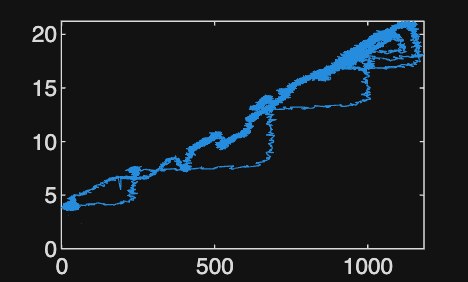

figure 
plot(ts.act(1).nozzle_pressure,ts.thrust_measured)

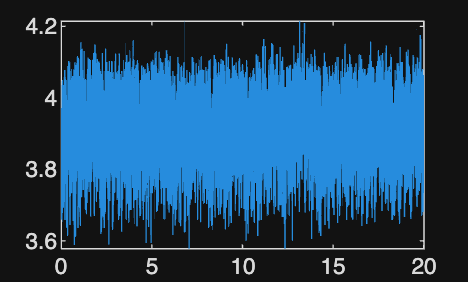


ts.t(1);
ts.t(end);
angle = ts.act(1).valveAngle;
closed_filter = angle<10;
tare = ts.thrust_measured(closed_filter);

figure  
plot(ts.t(closed_filter), tare)

tare = mean(tare)

tare = 3.9090

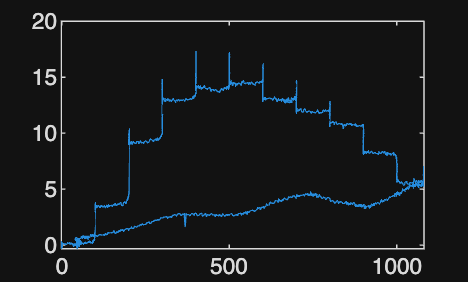

thrust_net = ts.thrust_measured - tare;
figure
plot(ts.act(1).valveAngle, thrust_net)

## force plot

figure 
filters = ts.t>15 & ts.t < 35

filters = 84230×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


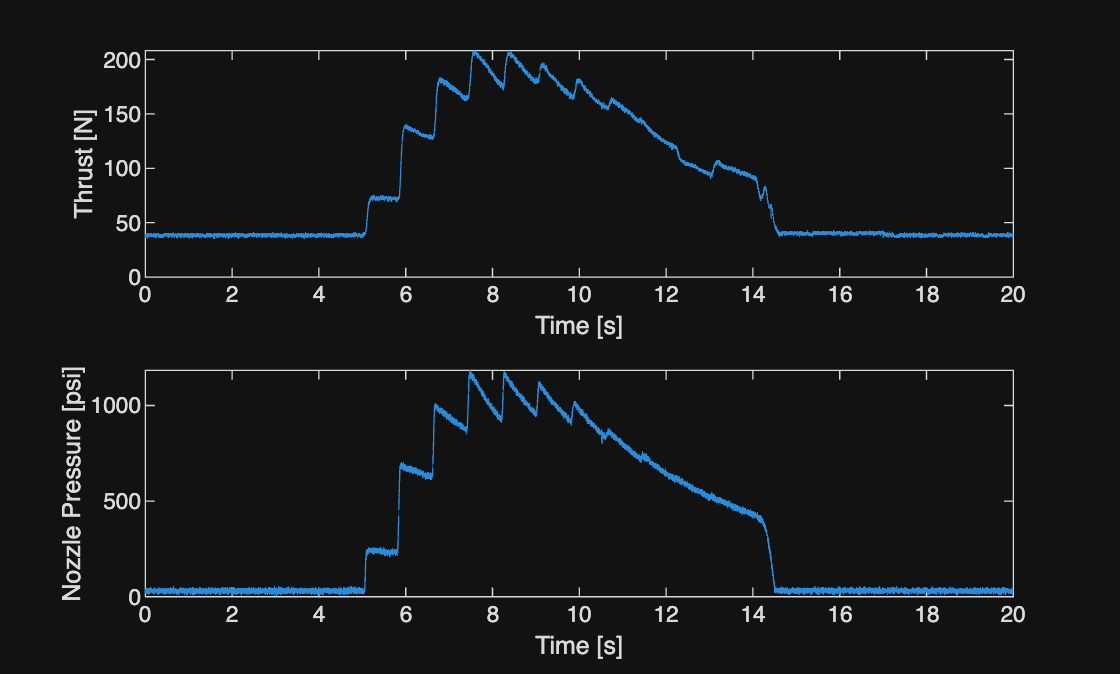

subplot(2,1,1)

plot(ts.t(filters)-15,ts.thrust_measured(filters)*9.81)

% xlabel('Time [s]')

ylabel('Thrust [N]')
xlabel('Time [s]')

subplot(2,1,2)
plot(ts.t(filters)-15, ts.act(1).nozzle_pressure(filters))
xlabel('Time [s]')
ylabel('Nozzle Pressure [psi]')